# Numerical Methods Example

Numerical solutions for ordinary lineal differential equations $\frac{\textrm{dy}}{\textrm{dx}}=f\left(x,y\right)$

**Tecnológico de Monterrey Campus Guadalajara**

**Juan Sebastian Gonzalez, A01644942, Bloque F1014B, Grupo 317**

## Introduction

This script is a recompilation of the work in my college Matlab course, which focused on numerical methods for ordinary differential equations, and provides 3 examples for comparing the different methods seen in class. The methods covered are Euler's method, Runge-Kutta methods of second order, Middle Point, Heun and Ralston method, and Runge-Kutta of fourth order. The script graphs all these methods and compares them to each other and the analytic solution.

## Example A


$$\textrm{RC}\frac{\textrm{dV}}{\textrm{dt}}+V=0\to \frac{\textrm{dV}}{\textrm{dt}}=-\frac{V}{\textrm{RC}}$$



$$\frac{\textrm{dV}}{\textrm{dt}}=-\frac{V}{\textrm{RC}}\to \int \frac{1}{V}\textrm{dV}=\int \frac{-1}{\textrm{RC}}\textrm{dt}\to \ln \left(V\right)=\frac{t}{\textrm{RC}}+C\to V\left(t\right)=e^{\frac{-t}{\textrm{RC}}+C_o } =e^{C_o } e^{\frac{-t}{\textrm{RC}}} =V_o e^{\frac{-t}{\textrm{RC}}}$$



$$V\left(t\right)=V_o e^{\frac{-t}{\textrm{RC}}}$$


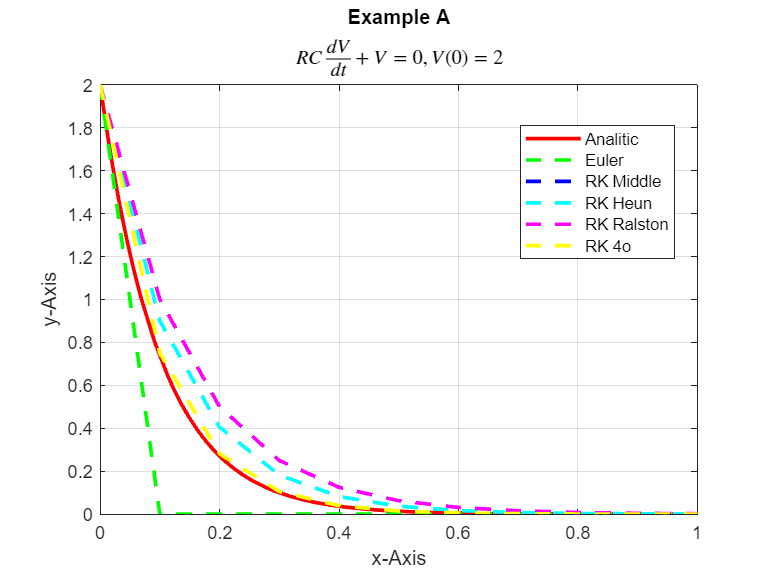

TABLA_COMPARATIVA = 11×6 table
     analitic     euler_method     middle         heun        ralston        rk4    
    __________    ____________    _________    __________    _________    __________

             2         2                  2             2            2             2
       0.73576         0                  1           0.9            1          0.75
       0.27067         0                0.5         0.405          0.5       0.28125
      0.099574         0               0.25       0.18225         0.25       0.10547
      0.036631         0              0.125      0.082012        0.125      0.039551
      0.013476         0             0.0625      0.036906       0.0625      0.014832
     0.0049575         0            0.03125      0.016608      0.03125     0.0055618

TABLA_ERROR = 11×5 table
    err_euler    err_middle    err_heun    err_ralston    err_rk4 
    _________    __________    ________    ___________    ________

        0               0            0             0             0
        1         0.35914      0.22323       0.35914      0.019356
        1         0.84726      0.49628       0.84726      0.039086
        1          1.5107      0.83029        1.5107      0.059198
        1          2.4124       1.2389        2.4124        0.0797
        1          3.6379       1.7386        3.6379        0.1006
        1          5.3036         2.35        5.3036        0.1219
        1          7.5674       3.0978        7.5674       0.14362
        1          10.644       4.0125        10.644       0.16575
        1          14.826       5.1314        14.826       0.18832


clc; clearvars; close all;

RC = 0.1;
edo = @ (x,y) -y/RC;
analitic = @ (x) 2*exp(-10*x);
y0 = 2;

x0 = 0;
xf = 1;
h = 0.1;

subtitle = '$RC\frac{dV}{dt} + V = 0, V(0) = 2$';
odePlot(analitic, edo, y0, x0, xf, h, 'Example A', subtitle)

## Example B

$y\frac{\textrm{dy}}{\textrm{dx}}=\frac{e^x }{1+e^x }\to \frac{\textrm{dy}}{\textrm{dx}}=\frac{1}{y}\frac{e^x }{1+e^x }$,$y\left(0\right)=1$


$$\frac{\textrm{dy}}{\textrm{dx}}=\frac{e^x }{y\left(1+e^x \right)}\to \int y\textrm{dy}=\int \frac{e^x }{1+e^x }\textrm{dx}\to \frac{1}{2}y^2 =\ln \left(e^x +1\right)+C\to y=\pm \sqrt{2}\sqrt{\ln \left(e^x +1\right)+C}$$



$$y\left(0\right)=\pm \sqrt{2}\sqrt{\ln \left(e^0 +1\right)+C}=1\to \pm \sqrt{\ln \left(2\right)+C}=\frac{1}{\sqrt{2}}\to \ln \left(2\right)+C=\frac{1}{2}\to C=\frac{1}{2}-\textrm{ln2}\to y\left(t\right)=\sqrt{2\ln \left(\frac{e^x +1}{2}\right)+1}$$


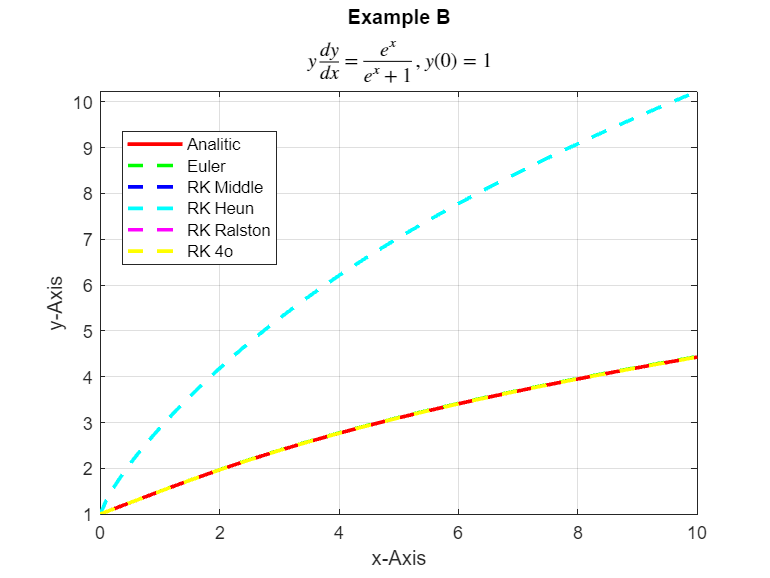

TABLA_COMPARATIVA = 101×6 table
    analitic    euler_method    middle     heun     ralston     rk4  
    ________    ____________    ______    ______    _______    ______

          1             1            1         1         1          1
       1.05          1.05         1.05    1.2875      1.05       1.05
        1.1           1.1          1.1    1.5214       1.1        1.1
       1.15          1.15         1.15    1.7283      1.15       1.15
     1.1999        1.1999       1.1999    1.9181    1.1999     1.1999
     1.2497        1.2498       1.2497     2.096    1.2497     1.2497
     1.2995        1.2996       1.2995    2.2648    1.2995     1.2995
     1.3491        1.3493       1.3491    2.4266    1.3491     1.3491
     1.3985        1.3988       1.3985    2.5825    1.3985     

TABLA_ERROR = 101×5 table
    err_euler     err_middle    err_heun    err_ralston     err_rk4  
    __________    __________    ________    ___________    __________

             0             0          0              0              0
     4.721e-07    2.3019e-07    0.22618     6.5467e-08     3.9306e-11
    5.0669e-06     7.575e-07    0.38311     3.8372e-07     1.4194e-10
    1.6943e-05    1.4051e-06    0.50289     9.2689e-07     2.8776e-10
    3.7689e-05    2.0612e-06    0.59855     1.6578e-06     4.6006e-10
    6.7846e-05    2.6569e-06    0.67711     2.5364e-06     6.4522e-10
    0.00010726    3.1522e-06    0.74286     3.5232e-06     8.3234e-10
    0.00015532    3.5266e-06    0.79867     4.5815e-06      1.013e-09
    0.00021114    3.7727e-06     0.8466     5.6787e-06     1.1807e-09
    0.00027369    3.8917e-06    0

clc; clearvars; close all;

edo = @ (x,y) exp(x)./(y.* (1+exp(x)) );
analitic = @ (x) sqrt(2*log((exp(x) + 1) / 2) + 1);
y0 = 1;

x0 = 0;
xf = 10;
h = 0.1;

subtitle = '$y\frac{dy}{dx} = \frac{e^{x}}{e^{x}+1}, y(0) = 1$';
odePlot(analitic, edo, y0, x0, xf, h, 'Example B', subtitle)

## Example C

$\frac{\textrm{dy}}{\textrm{dx}}=\left(y+1\right)\left(x+1\right)\cos \left(x^2 +2x\right)$,$y\left(0\right)=4$


$$\begin{array}{l}
\frac{\textrm{dy}}{\textrm{dx}}=\left(y+1\right)\left(x+1\right)\cos \left(x^2 +2x\right)\to \int \frac{1}{y+1}\textrm{dy}=\int \left(x+1\right)\cos \left(x^2 +2x\right)\textrm{dx}\\
\to \ln \left(y+1\right)=\frac{1}{2}\sin \left(x^2 +2x\right)+C\to y=e^{\frac{1}{2}\sin \left(x^2 +2x\right)+C} -1
\end{array}$$



$$y\left(0\right)=e^{\frac{1}{2}\sin \left(0^2 +2\left(0\right)\right)+C} -1=4\to e^C =5\to C=\ln \left(5\right)\to y\left(x\right)=5e^{\frac{1}{2}\sin \left(x^2 +2x\right)} -1$$


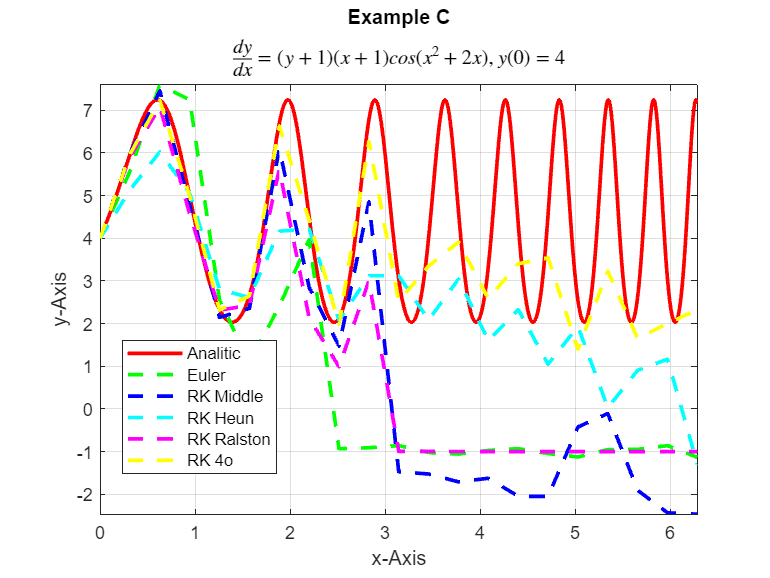

TABLA_COMPARATIVA = 21×6 table
    analitic    euler_method    middle      heun     ralston      rk4  
    ________    ____________    _______    ______    ________    ______

          4              4            4         4           4         4
      5.971         5.5708       5.9835    5.1335      5.9057    5.9704
     7.2302         7.5977       7.4557    6.0256      7.0799    7.2301
     4.9864         7.2435       4.7687    5.0574      4.5679    4.9853
     2.3284         2.5504       2.1429    2.7999      2.3121    2.3198
     2.6594          1.088       2.3575    2.6103      2.4291     2.646
     6.6951         2.4053       6.0953    4.1669      5.6129    6.6297
     4.4964         3.9683       2.8488    4.2133       2.132     4.425
     2.1247       -0.93472       1.4755    2

TABLA_ERROR = 21×5 table
    err_euler    err_middle    err_heun    err_ralston     err_rk4  
    _________    __________    ________    ___________    __________

           0             0            0             0              0
    0.067025     0.0020869      0.14027      0.010939     0.00010823
    0.050823      0.031186      0.16661      0.020787     1.4247e-05
     0.45265      0.043662     0.014241       0.08392     0.00020874
     0.09534      0.079666      0.20252     0.0069867      0.0037066
     0.59091       0.11353     0.018472      0.086617       0.005063
     0.64073      0.089587      0.37762       0.16164      0.0097718
     0.11744       0.36643     0.062955       0.52583       0.015877
      1.4399       0.30552     0.022147       0.53571       0.066101
      1.1343       0.28409      0.53931      

clc; clearvars; close all;

edo = @ (x,y) (y+1).*(x+1).*cos(x.^2 + 2*x);
analitic = @ (x) 5*exp((1/2) * sin(x.^2 + 2*x)) - 1;
y0 = 4;

x0 = 0;
xf = 2*pi;
h = (xf-x0)/20;

subtitle = '$\frac{dy}{dx} = (y+1)(x+1)cos(x^{2}+2x), y(0) = 4$';
odePlot(analitic, edo, y0, x0, xf, h, 'Example C', subtitle)

## Error Calculation

function [error] = odeError(yAnalitic, yNumeric)
    error = abs(yAnalitic - yNumeric)./yAnalitic;
end

## Comparison Plot of Methods

function [] = odePlot(analitic, edo, y0, x0, xf, h, plotTitle, plotSubtitle)
    x = x0:h:xf;
    analitic_y = analitic(x);
    fplot(analitic, [x0 xf], 'Color','r', 'LineWidth',2, 'LineStyle','-')

    hold on

    euler_y = euler(edo, y0, [x0 xf], h);
    plot(x, euler_y, 'LineWidth',2, 'LineStyle', '--', 'Color', 'g')

    middle_y = rk_2_middle(edo, y0, [x0 xf], h);
    plot(x, middle_y , 'LineWidth',2, 'LineStyle', '--', 'Color', 'b')

    heun_y = rk_2_heun(edo, y0, [x0 xf], h);
    plot(x, heun_y, 'LineWidth',2, 'LineStyle', '--', 'Color', 'c')

    ralston_y = rk_2_ralston(edo, y0, [x0 xf], h);
    plot(x, ralston_y, 'LineWidth',2, 'LineStyle', '--', 'Color', 'm')

    rk4_y = rk_4(edo, y0, [x0 xf], h);
    plot(x, rk4_y, 'LineWidth',2, 'LineStyle', '--', 'Color', 'y')

    grid on
    xlabel("x-Axis"), ylabel("y-Axis");
    title(plotTitle);
    subtitle(plotSubtitle,'interpreter','latex');
    legend('Analitic', 'Euler', 'RK Middle', 'RK Heun', 'RK Ralston', 'RK 4o', 'Location','best')

    hold off

    analitic = analitic_y';
    euler_method = euler_y';
    middle = middle_y';
    heun = heun_y';
    ralston = ralston_y';
    rk4 = rk4_y';
    TABLA_COMPARATIVA = table(analitic, euler_method, middle, heun, ralston, rk4)

    err_euler = odeError(analitic_y, euler_y)';
    err_middle = odeError(analitic_y, middle_y)';
    err_heun = odeError(analitic_y, heun_y)';
    err_ralston = odeError(analitic_y, ralston_y)';
    err_rk4 = odeError(analitic_y, rk4_y)';
    TABLA_ERROR = table(err_euler, err_middle, err_heun, err_ralston, err_rk4)
end